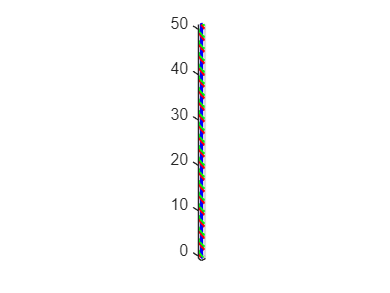

% 'out' is Simulink output variable.
P = transpose(out.P.Data);
tP = out.P.Time;
n = length(out.R.Data);
for i = 1:n
    R(:,:,i) =-1 * eye(3) * out.R.Data(:,:,i);
end
tR = out.R.Time;

hold on
[x,y,z,u,v,w] = genQuiver3Data(P,R);
q = quiver3(x,y,z,u(1,:),v(1,:),w(1,:),'r');
q.Marker = '.';
q.MaxHeadSize = 0.01;
q.AutoScale = true;
q.AutoScaleFactor = 0.5;
q = quiver3(x,y,z,u(2,:),v(2,:),w(2,:),'g');
q.Marker = '.';
q.MaxHeadSize = 0.01;
q.AutoScale = true;
q.AutoScaleFactor = 0.5;
q = quiver3(x,y,z,u(3,:),v(3,:),w(3,:),'b');
q.Marker = '.';
q.MaxHeadSize = 0.01;
q.AutoScale = true;
q.AutoScaleFactor = 0.5;
axis equal
hold off